# Abdul Ahad Butt

262517

BEE 10 C

# Recording the Audio

Before we can actually use the audiorecorder function, we must define some variables to be used

filename = 'ahadhelp4.wav';
Fs = 44100; 
nBits = 8; 
nChannels = 1; 
ID = -1; % default audio input device
T = 2;

Now we record our audio file and save it in a .wav format for further use, so we don't have to re-record everytime

recObj = audiorecorder(Fs,nBits, nChannels, ID);


disp('Start speaking.')
recordblocking(recObj,T);
disp('End of Recording.');

play(recObj); % Checking to see if our audio was correctly picked up


doubleArray = getaudiodata(recObj);
plot(doubleArray);
title('Audio Signal (Double)');

audiowrite(filename, doubleArray, Fs);

clear ID nBits nChannels Fs;
clear recObj doubleArray T;

# Reading in the Audio

Now that we have saved our audio file in a .wav format, we may invoke the audioread function to read it evertime our script is run

filename = 'ahadhelp4.wav';
[x, Fs] = audioread(filename);
x = transpose(x);
L = length(x);
T = L / Fs;
t = linspace(0, T, L);
sound(x, Fs);

# Plotting the Spectrum

First we will define a function to assist in the plotting of frequencies

Let us get the one sided frequency spectrum of our sample signal

% One sided frequency transform of x
X = fft(x);
P2 = abs(X/L);
P1 = P2(1: L/2 + 1);
P1(2:end) = 2 * P1(2:end);
X = P1;
clear P2 P1;
% One sided frequency array
f = Fs * (1:(L/2+1)) / L; 
w = 2 * pi * f;

The following variable holds the endpoint of the frequency we want to see. I have defined this to better see the part of the spectrum worth looking at.

FREQUENCY_END = 1500;

Now we will plot the signal and its spectrum

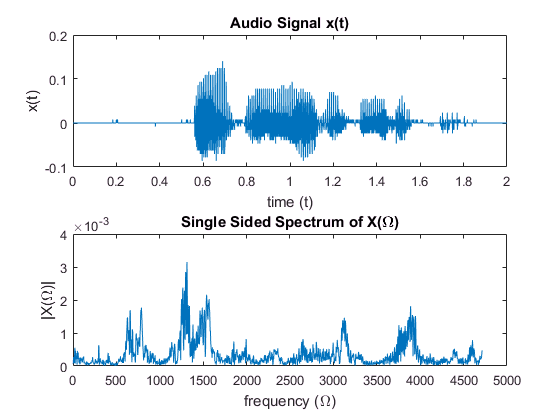

figure
subplot(2, 1, 1);
plot(t, x);
title('Audio Signal x(t)')
xlabel('time (t)')
ylabel('x(t)')

subplot(2, 1, 2);
plot(w(1:FREQUENCY_END), X(1:FREQUENCY_END));
title('Single Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X(\Omega)|')

# Designing a Low Pass Analog Filter

Now we are going to design a third order butterworth filter to "clean" our signal before sampling it. This is done to prevent aliasing as sometimes the highest frequency components of a signal are simply noise, or they do not contain useful data. 

## The butterworth filter and the cutoff frequency

We use a third order filter because we want a non-steep slow.

We use 5kHz cutoff frequency because normal speech usually does not contain frequency components over this threshold.

We will also plot the frequency response of these filters

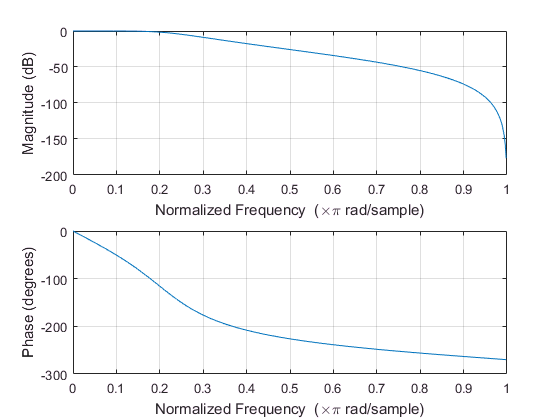

fc = 5000;  % Cutoff frequency
[b, a] = butter(3, fc/(Fs/2));
figure
freqz(b, a);

## Plotting the signal and its spectrum

Let us now look at our signal after it passing through our filter

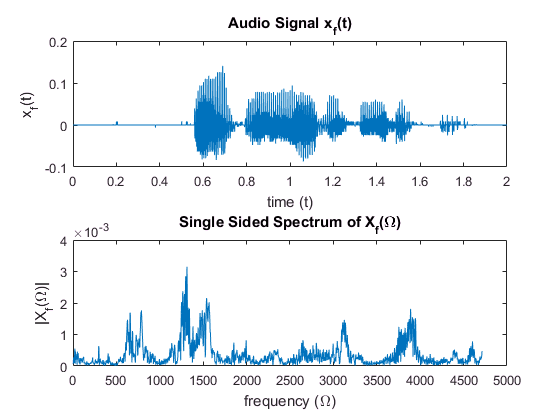

xf = filter(b, a, x);
Xf = fft(xf);

P2 = abs(Xf/L);
P1 = P2(1: L/2 + 1);
P1(2:end) = 2 * P1(2:end);
Xf = P1;
clear P2 P1;

figure
subplot(2, 1, 1);
plot(t, xf);
title('Audio Signal x_f(t)')
xlabel('time (t)')
ylabel('x_f(t)')

subplot(2, 1, 2);
plot(2 * pi * f(1:FREQUENCY_END), Xf(1:FREQUENCY_END));
title('Single Sided Spectrum of X_f(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_f(\Omega)|')


clear b a;

# Applying the Zero-Order Hold filter

Now we are ready to sample our continous signal into discrete instances.

We should be careful to choose a sampling period T, such that aliasing does not occur

For this reason F_sample should be greater than Fs/2.

T_samp = 2;
x_n = [];
for i = 1:T_samp:length(x)
  x_n(i:i + T_samp - 1) = x(i) .* ones(1, T_samp);
end   
clear i;

Xn = fft(x_n);
P2 = abs(Xn/L);
P1 = P2(1: L/2 + 1);
P1(2:end) = 2 * P1(2:end);
Xn1 = P1;
clear P2 P1;
f2 = Fs * (-L/2:L/2-1) / L;
w2 = 2 * pi * f2;

## Plotting the signal and its spectrum

Let us see our signal and its spectrum after being converted

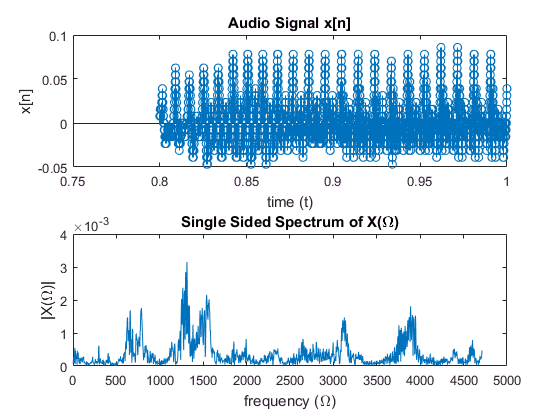

figure
subplot(2, 1, 1);
stem(t(0.4*L:0.5*L), x_n(0.4*L:0.5*L)); % Plotting a section as it does get jumbled up
title('Audio Signal x[n]')
xlabel('time (t)')
ylabel('x[n]')

subplot(2, 1, 2);
plot(w(1:FREQUENCY_END), abs(Xn1(1:FREQUENCY_END)));
title('Single Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X(\Omega)|')

## Wrong way to sample

Let us take a look at what would happen if we do not take care of our Nyquist requirements

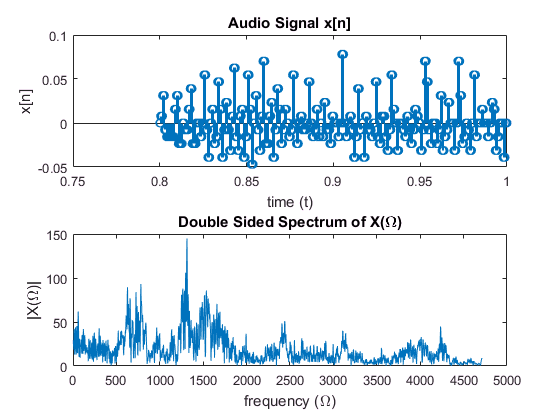

T_wsamp = 50;
x_wrong = [];
for i = 1:T_wsamp:length(x)
  x_wrong(i:i + T_wsamp - 1) = x(i) .* ones(1, T_wsamp);
end   




X_wrong = fft(x_wrong);
figure
subplot(2, 1, 1);
stem(t(0.4*L:0.5*L), x_wrong(0.4*L:0.5*L)); %Plotting a section as it does get jumbled up
title('Audio Signal x[n]')
xlabel('time (t)')
ylabel('x[n]')

subplot(2, 1, 2);
plot(w(1:FREQUENCY_END), abs(X_wrong(1:FREQUENCY_END)));
title('Double Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X(\Omega)|')


clear X_wrong x_wrong T_wsamp T_samp;

# Downsampling

Now let us downsample our discrete signal by a factor of M, and see what our signal looks like in comparison to the original. For this we will use the decimate function.

The decimate function works by taking a sample after ever M instance and storing it in an array of size (L/2)

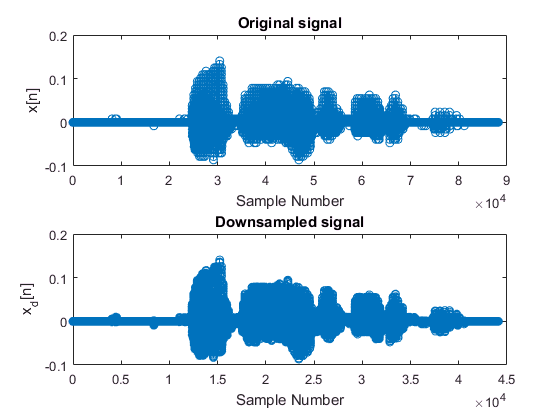

M = 2; % Downsampling Factor
x_d = decimate(x_n, M);
Ld = length(x_d);
t_d = linspace(0,T,length(x_d));
Xd = fft(x_d);

P2 = abs(Xd/Ld);
P1 = P2(1: Ld/2 + 1);
P1(2:end) = 2 * P1(2:end);
Xd = P1;
clear P2 P1;


figure
subplot(2, 1, 2);
stem(x_d)
title('Downsampled signal');
xlabel('Sample Number')
ylabel('x_d[n]')

subplot(2, 1, 1);
stem(x_n)
title('Original signal');
xlabel('Sample Number')
ylabel('x[n]')

Lets compare the spectrum of our signal before and after downsampling

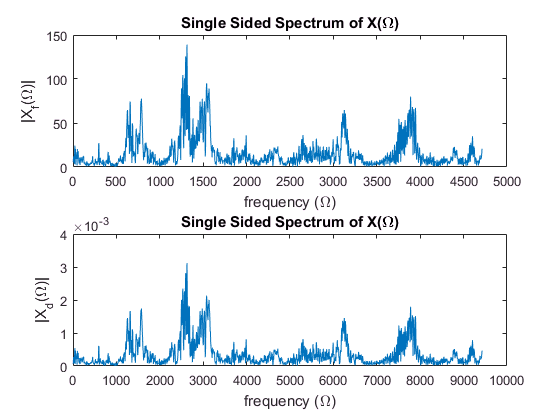

figure
subplot(2, 1, 1);
plot(w(1:FREQUENCY_END), abs(Xn(1:FREQUENCY_END)));
title('Single Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_f(\Omega)|')

subplot(2, 1, 2);
plot(M * w(1:FREQUENCY_END), Xd(1:FREQUENCY_END));
title('Single Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_d(\Omega)|')

# Adding noise

Next we add noise to our downsampled signal

First let us take a look at the noise

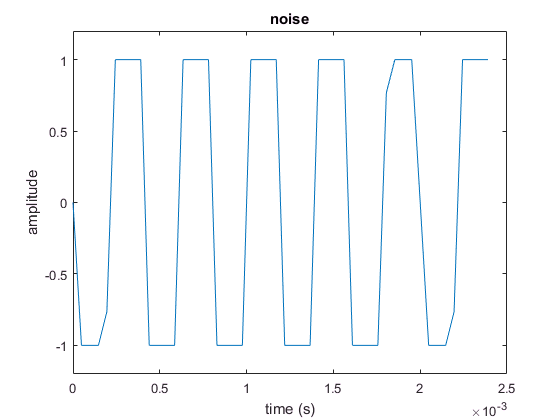

[x_noise, Fsnoise] = audioread('noise.wav');
tnoise = linspace(0,T,length(x_noise));
figure
plot(tnoise(1:50), x_noise(1:50));
xlabel('time (s)');
ylabel('amplitude');
title('noise');
ylim([-1.2, 1.2]);

Now unfortunately, our noise and signal sampling frequency isn't the same. This makes adding the two signals difficult. Nevertheless, we will employ the use of the interp1 function to make our lives easier by converting the noise to the same sampling frequency. 

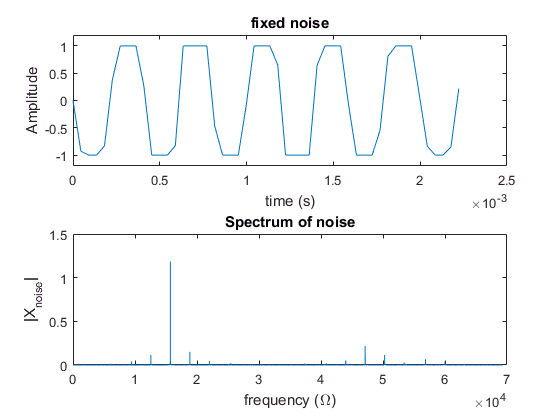

figure
xnoise = interp1(tnoise, x_noise, t_d);
f_d = (Fs/2) * (0:Ld/2)/Ld;
wd = 2*pi*f_d;

% Calculating the fourier transform of xnoise, just for fun
Xnoise = fft(xnoise);
P2 = abs(Xnoise/Ld);
P1 = P2(1: Ld/2 + 1);
P1(2:end) = 2 * P1(2:end);
Xnoise = P1;
clear P2 P1;

subplot(2,1,1);
plot(t_d(1:50), xnoise(1:50));
xlabel('time (s)');
ylabel('Amplitude');
title('fixed noise');
ylim([-1.2, 1.2]);

subplot(2,1,2)
plot(wd, Xnoise);
title('Spectrum of noise');
xlabel('frequency (\Omega)');
ylabel('|X_{noise}|');

Now we add the noise to the downsampled signal

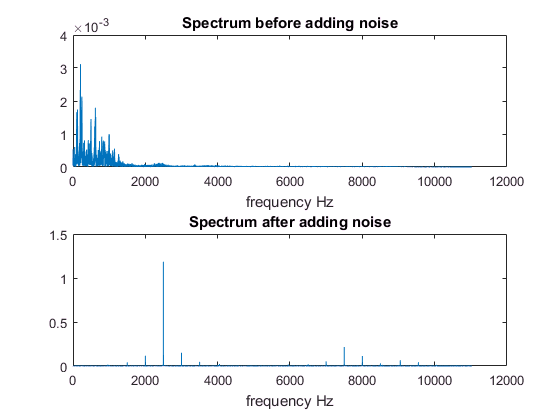

sn = x_d + xnoise;




Sn = fft(sn);
P2 = abs(Sn/Ld);
P1 = P2(1: Ld/2 + 1);
P1(2:end) = 2 * P1(2:end);
Sn = P1;
clear P2 P1;




figure
subplot(2,1,1)
plot(f_d, Xd)
title('Spectrum before adding noise');
xlabel('frequency Hz');

subplot(2,1,2)
plot(f_d, Sn)
title('Spectrum after adding noise');
xlabel('frequency Hz');

The noise completely overshadows the our signal

# Making a low pass filter 

Now we will make a low pass filter to cut high frequency noise as much as we can

f_cnoise = 2000;
[b, a] = butter(6, f_cnoise/(Fs));


Let us take a look at our filter

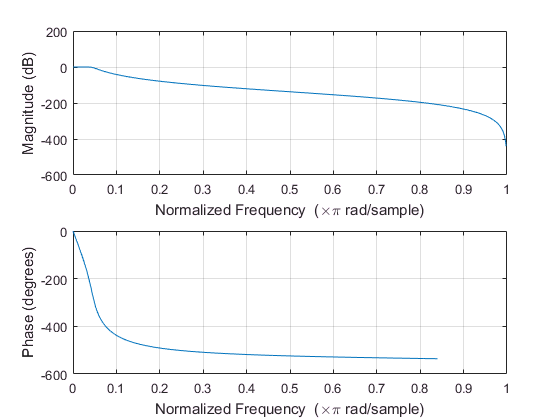

figure
freqz(b,a);

Now let us see our output after passing throough this filter

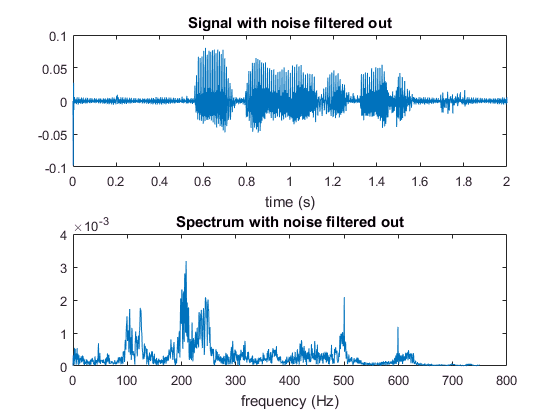

y = filter(b,a,sn);

Y = fft(y);
P2 = abs(Y/Ld);
P1 = P2(1: Ld/2 + 1);
P1(2:end) = 2 * P1(2:end);
Y = P1;
clear P2 P1;

figure
subplot(2,1,1)
plot(t_d, y)
title('Signal with noise filtered out');
xlabel('time (s)')
subplot(2,1,2)
plot(f_d(1:FREQUENCY_END), Y(1:FREQUENCY_END));
title('Spectrum with noise filtered out');
xlabel('frequency (Hz)');

# Upsampling

Now that we have finished filtering the signal, we are ready to upsample it.

We will be using the predefined interp function for this. The interp function interpolated the data and returns N*length(x) samples back

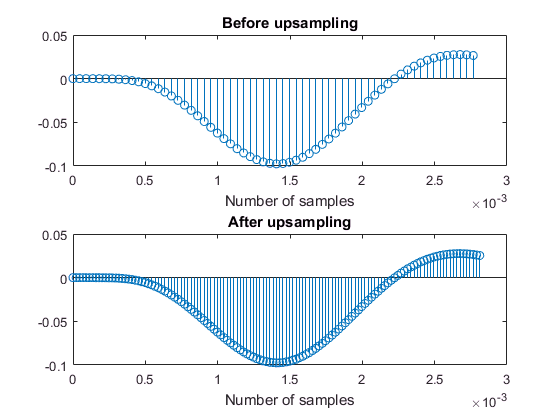

U = 2; % Upsampling factor
yu = interp1(t_d, y, t); %Replace t_d and x_d with output from low pass filter when you get a chance
figure
subplot(2,1,1);
stem(t_d(1:62),y(1:62));
xlabel('Number of samples');
title('Before upsampling');
subplot(2,1,2);
stem(t(1:125),yu(1:125));
xlabel('Number of samples');
title('After upsampling');

Finally, let us take a look at the spectrums before and after upsampling

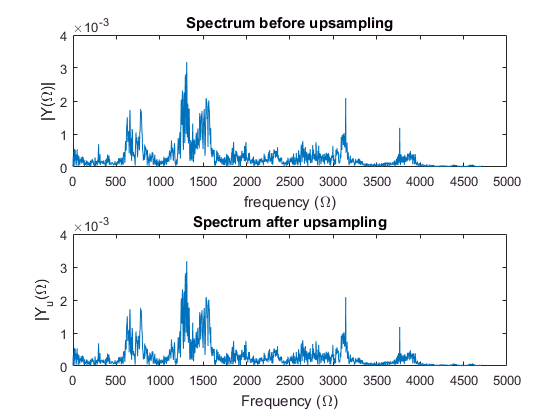

Yu = fft(yu);
P2 = abs(Yu/L);
P1 = P2(1: L/2 + 1);
P1(2:end) = 2 * P1(2:end);
Yu = P1;
clear P2 P1;

figure
subplot(2,1,1)
plot(wd(1:FREQUENCY_END), Y(1:FREQUENCY_END))
title('Spectrum before upsampling');
ylabel('|Y(\Omega)|');
xlabel('frequency (\Omega)');


subplot(2,1,2)
plot(wd(1:FREQUENCY_END),Yu(1:FREQUENCY_END))
title('Spectrum after upsampling');
ylabel('|Y_{u}(\Omega)');
xlabel('Frequency (\Omega)');

Xnoise = fftshift(fft(xnoise));
Xnoise = abs(Xnoise);


figure
subplot(2,1,1);
plot(2*pi*f_d,X_d);
title('Double Sided Spectrum of X_d(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_d(\Omega)|')

subplot(2,1,2);
plot(2*pi*f_d,Xnoise);
title('Double Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_{noise}(\Omega)|')




Getting a "good noise"

x_noise = -sin(6e4 * t_d);
X_noise = abs(fftshift(fft(x_noise)));

Now we can add the two and analyse the difference in their spectrums

s_n = 0.25* x_noise + transpose(x_d);
%S_n = abs(fftshift(fft(x_noise)));

X_d = fftshift(fft(x_d));
X_d = abs(X_d);
Ln = length(X_d);
S_n = 0.0025 * transpose(X_noise) + X_d;


figure
subplot(2,1,1);
plot(f_d,X_d);

subplot(2,1,2);
plot(f_d,S_n);


# Making a low pass filter 

Now we will make a low pass filter to cut hight frequency noise as much as we can

wc_noise = 12e4;
fc_noise = wc_noise/(2*pi);

x_last = ifft(S_n);
[b, a] = butter(3, fc/(2*Fs));
x_final = filter(b,a,x_last);
figure
%plot(x_final(50:end));
plot(f_d,abs(fftshift(fft(x_final))));


# Upsampling

Now that we have finished filtering the signal, we are ready to upsample it.

We will be using the predefined interp function for this. The interp function interpolated the data and returns N*length(x) samples back

U = 2; % Upsampling factor
xu = interp1(t_d, y, t); %Replace t_d and x_d with output from low pass filter when you get a chance
subplot(2,1,1);
stem(t_d(1:62),x_d(1:62));

subplot(2,1,2);
stem(t(1:125),xu(1:125));


## Comparing the spectrums before and after upsampling

figure
subplot(2,1,1)
plot(f_d, abs(fft(x_d)));
title('Before');
subplot(2,1,2)
plot(f2, abs(fft(xu)));
title('After');



function P1 = offt (x, L)
  X = fft(x);
  P2 = abs(X/L);
  P1 = P2(1: L/2 + 1);
  P1(2:end) = 2 * P1(2:end);
end


function y = zoh (x, T)
y = [];
y = 0;
for i = 1:T:length(x)
  % sprintf('%d - %d - %d', i, i + T, x(i))
  % size(x(i))
  % size(1, ones(T))
  y(i:i + T - 1) = x(i) .* ones(1, T);
end   

y = transpose(y);
end
